## 3.5 Mini exercise: Steady states via Symbolic, graphical (phase line), numerical (fzero), and ode solver

What value does an ODE model go to steady state? When du/dt=0!

Gene expression with some positive feedback in expression:

dPdt =@(P) (a_0 + a_1*P) - b*P;

a_1 = 0.5

Plot dPdt versus P. (Note this is different from dudt versus t)

What value does this predict a steady state protein level? 

Find the steady state using 3 approaches:

- Use symbolic math (and paper and pencil) to find the steady state.

- Use ode45 to numerically find the steady state.

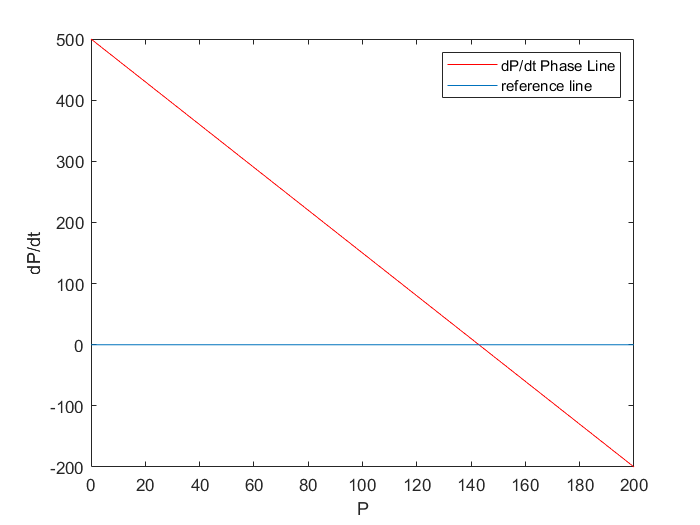

% define ODE and parameters
a_0 = 500; % molecules per hour
a_1 = 0.5; % molecules per hour, per existing molecule of A
b = 4; % 1/hrs
dPdt =@(P) (a_0 + a_1*P) - b*P;

% Find the steady state by plotting the dP/dt versus P
PArray = linspace(0,200,200);
dPdtPhaseLine = dPdt(PArray);
figure;
plot(PArray,dPdtPhaseLine,'r');
ylabel('dP/dt');
xlabel('P');
refline(0,0); % horizontal line at dPdt=0
legend('dP/dt Phase Line','reference line');

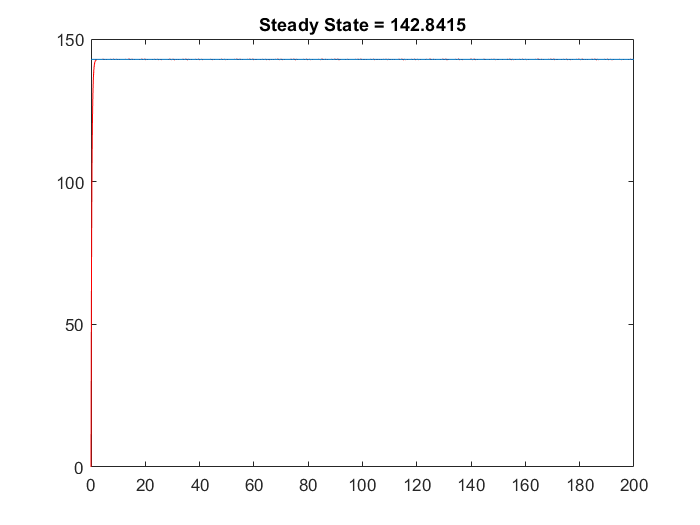

% Find the steady state symbolically ("pencil and paper")

% Find the steady state by simulating the ODE
[T,P] = ode45(@(t,x)dPdt(x), [0,200], 0);
plot(T,P,'r');
refline(0,P(end));
title(['Steady State = ', num2str(P(end))]);